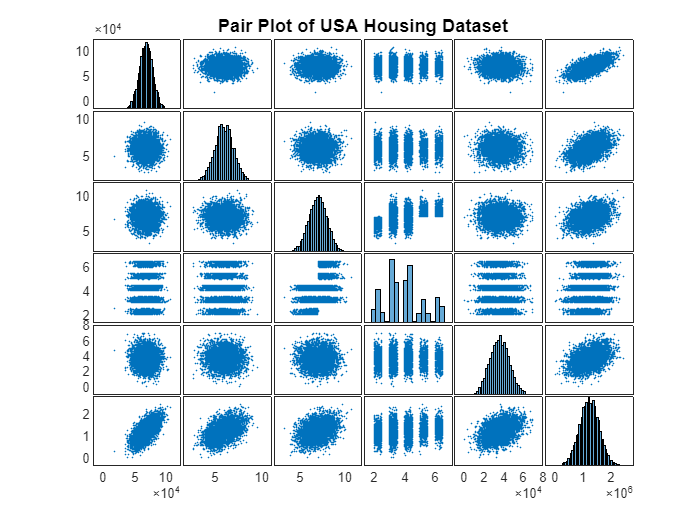


% Load the dataset
loadedData = load('USAHousing1.mat');

% Extract the table from the loaded data
USAHousing1 = loadedData.USAHousing1;

% Extract the numerical data from the table
data = [USAHousing1.AvgAreaIncome, USAHousing1.AvgAreaHouseAge, ...
        USAHousing1.AvgAreaNumberOfRooms, USAHousing1.AvgAreaNumberOfBedrooms, ...
        USAHousing1.AreaPopulation, USAHousing1.Price];

% Create pairwise scatter plots
plotmatrix(data);

% Add title and axis labels
title('Pair Plot of USA Housing Dataset');

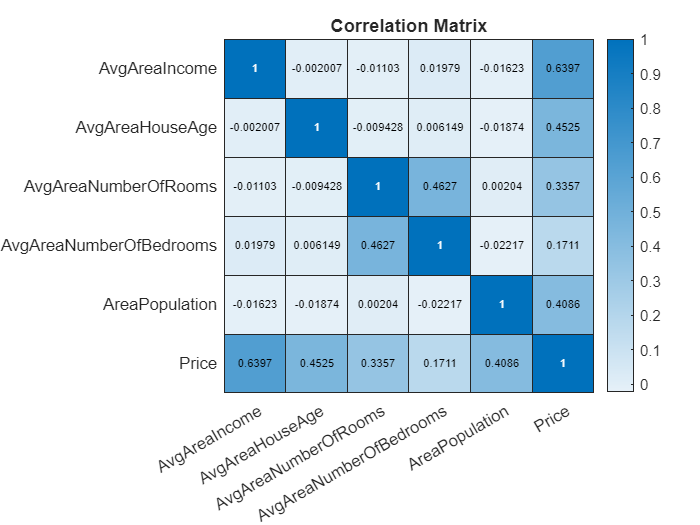

% Create a heatmap of the correlation matrix
correlationMatrix = corr(data);
labels = {'AvgAreaIncome', 'AvgAreaHouseAge', 'AvgAreaNumberOfRooms', ...
          'AvgAreaNumberOfBedrooms', 'AreaPopulation', 'Price'};


heatmap(labels, labels, correlationMatrix);
title('Correlation Matrix');

X = [USAHousing1.AvgAreaIncome, USAHousing1.AvgAreaHouseAge, ...
     USAHousing1.AvgAreaNumberOfRooms, USAHousing1.AvgAreaNumberOfBedrooms, ...
     USAHousing1.AreaPopulation];

% Select the 'Price' column for y
y = USAHousing1.Price;

Xfeatures = X;
Xs = [ones(size(y,1),1) Xfeatures];
AllData = [Xs y];

cv = cvpartition(size(AllData,1), 'HoldOut', 0.2);
Index = cv.test;

TestData = AllData(Index,:);
TrainData = AllData(~Index,:);

X_train = TrainData(:,1:end-1);

y_train = TrainData(:,end);

X_test = TestData(:,1:end-1);
y_test = TestData(:,end);

%% Linear Regression through mathematics
Xt=X_train';
Th=(pinv (Xt* X_train) ) *Xt*y_train;
ypr=(Th' ) *X_test(1:end, : )';
ypr=ypr' ;
% Calculate MSE
disp ( 'MSE Linear Regression ');

MSE Linear Regression 


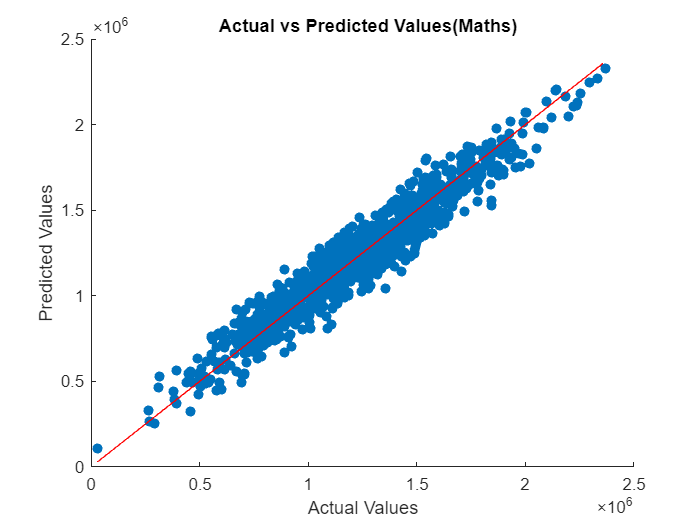

MSE=immse (y_test , ypr);
%Plot graph
figure
scatter (y_test,ypr,'filled')
% Label the axes
xlabel('Actual Values');
ylabel('Predicted Values');

% Add a title to the plot
title('  Actual vs Predicted Values(Maths)');

% Optionally, add a line of equality (y = x) for reference
hold on;
plot(y_test, y_test, 'r--');
hold off;

t0=Th(1);
t1=Th(2);
t2=Th(3);
t3=Th(4);
t4=Th(5);
t5=Th(6);

x0=ConvertToFixedPoint(X_test(:,1));
x1=ConvertToFixedPoint(X_test(:,2));
x2=ConvertToFixedPoint(X_test(:,3));
x3=ConvertToFixedPoint(X_test(:,4));
x4=ConvertToFixedPoint(X_test(:,5));
x5=ConvertToFixedPoint(X_test(:,6));



cv = cvpartition(size(X, 1), 'Holdout', 0.2);

% Get the indices for training and test sets
X_train1 = X(training(cv), :);
y_train1 = y(training(cv), :);

X_test1 = X(test(cv), :);
y_test1 = y(test(cv), :);


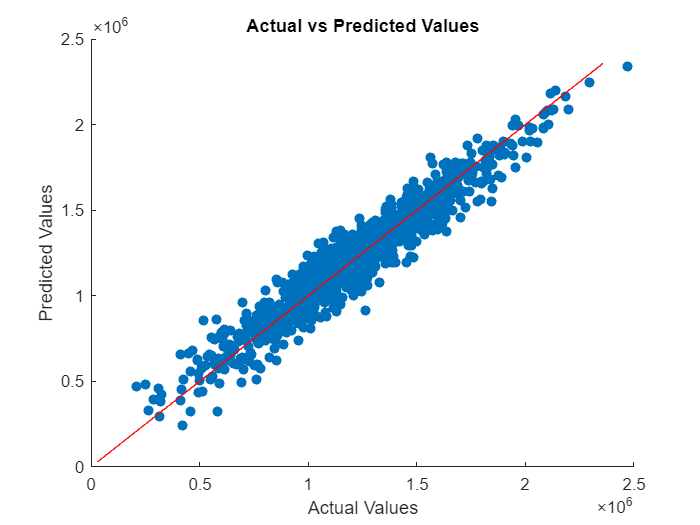

%% Linear Regression inbuilt model
lm = fitlm(X_train1, y_train1);
predictions = predict(lm, X_test1);


% Create a scatter plot of the actual vs predicted values
scatter(y_test1, predictions, 'filled');

% Label the axes
xlabel('Actual Values');
ylabel('Predicted Values');

% Add a title to the plot
title('Actual vs Predicted Values');

% Optionally, add a line of equality (y = x) for reference
hold on;
plot(y_test, y_test, 'r--');
hold off;